# 机器人基础大作业

19374128 白梓彤

## 建立机器人的模型

首先，机器人的参数如下。

clc, clear, clf
% ================================================================
% DOBOT 参数
% ================================================================
% 长度
l1 = 138/100;   % [m]
l2 = 135/100;   % [m]
l3 = 147/100;   % [m]
% 底座半径
r1 = 75/100;    % [m]
% 质量
m1 = 1.5;       % [kg]
m2 = 1;         % [kg]
m3 = 1;         % [kg]
% 惯性张量
I1 = zeros(3); I1(9) = 0.5*m1*r1*r1; 
I2 = zeros(3); % 由于质量集中，所以惯性张量为零矩阵
I3 = zeros(3); % 由于质量集中，所以惯性张量为零矩阵
% 质心位置（相对每个连杆的原点）
c1 = [0; 0; -l1/2];
c2 = [l2/2; 0; 0];
c3 = [l3; 0; 0];
% 关节角度限制
limit1 = [-90, 90]/180*pi;      % [rad]
limit2 = [5, 90]/180*pi;        % [rad]
limit3 = [-90, 10]/180*pi;      % [rad]
limit23 = [-70, 60]/180*pi;     % [rad]
% 重力加速度
g = 9.8; % [m/s^2]

### 运动学模型

采用面向对象编程的思想，将机械臂的连杆封装成类，具体代码在dobotLink.m中；将机械臂封装成类，具体代码在dobot.m中

下面建立运动学模型

% 类对象初始化参数
initStruct = struct( ...
    'length', [l1, l2, l3], ...
    'mass', [m1, m2, m3], ...
    'center', [c1, c2, c3], ...
    'inertia', cat(3, I1, I2, I3) ...
    );
% 构造一个机器人类
robot = dobot(initStruct);

robot是一个dobot类的对象，机器人的正运动学、逆运动学、绘图、运动学等都被封装成了这个类的方法。下面一一展示。

#### 正运动学

若机器人的三个关节角度分别为$\theta_1 = 60^\circ, \theta_2 = 30^\circ, \theta_3 = -30^\circ
$，则其从0坐标系到末端坐标系的其次变换矩阵如下：

robot.fkine([60 30 -30]/180*pi)

ans =     0.5000   -0.0000    0.8660    1.3196
    0.8660         0   -0.5000    2.2856
         0    1.0000    0.0000    2.0550
         0         0         0    1.0000


调用dobot中自定义的fplot方法，可以绘制机械臂在空间中的位姿。

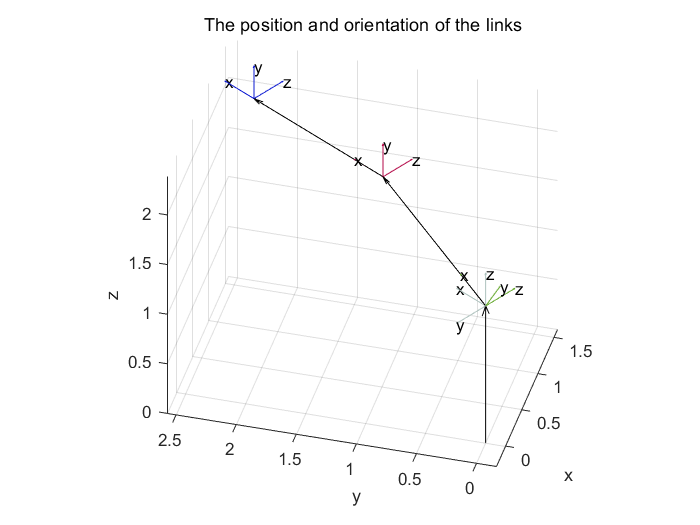

figure('Name','fkine')
robot.fplot([60 30 -30]/180*pi)
view([-74.89 37.09])

#### 逆运动学

给出末端位置（在绝对坐标系中），可以计算出各个关节的角度

itheta = robot.invkine([1.5, 2.3, 0.1])

itheta =     0.9929
    0.2733
   -0.4542


也使用上面提到的fplot函数，绘制出此时机械臂的位姿

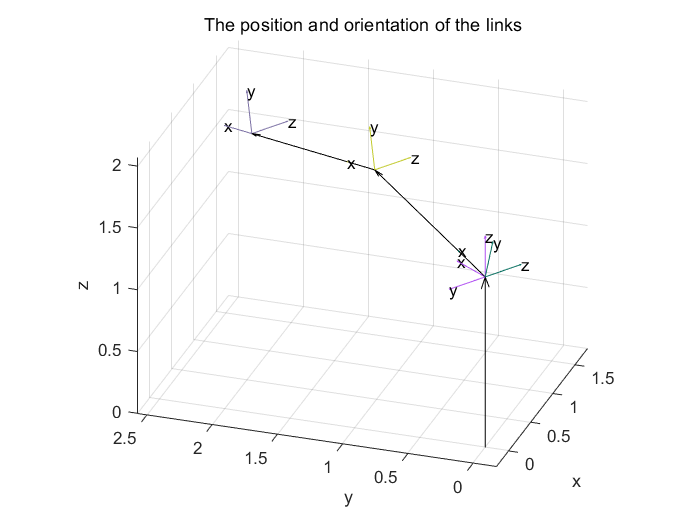

figure('Name','invkine')
robot.fplot(itheta)
view([-71.24 26.13])

### 动力学模型

前面在运动学模型中提到了，dobot类中不仅封装了与运动学相关的函数，也封装了动力学相关的函数。

#### 牛顿欧拉法

使用牛顿欧拉法，计算出在给定关节角度、角速度和角加速度时各个关节的扭矩。

th = [10; 20; 30]*pi/180; % rad
dth = [1; 2; 3];  % rad/s
ddth = [0.5; 1; 1.5];  % rad/s^2
n = robot.dynamic(th, dth, ddth);
n = n(3,1:3)

n =   -26.7377  -31.3888    4.3224


#### 雅可比矩阵

调用dobot类中的jacobi方法，可以计算出机械臂在给定的关节角度下的雅可比矩阵。

robot.jacobi([pi/6, pi/4, -pi/6])

ans =    -1.1873   -1.1562   -0.3295
    2.0564   -0.6675   -0.1902
         0    2.3745    1.4199
         0    0.5000    0.5000
         0   -0.8660   -0.8660
    1.0000         0         0


#### 海森矩阵

调用dobot类中的Hessian方法，可以计算出机械臂在给定的关节角度下的海森矩阵。

[H1, H2, H3] = robot.Hessian([pi/6, pi/4, -pi/6])

H1 =    -2.0564    0.6675    0.1902
    0.6675   -2.0564   -1.2297
    0.1902   -1.2297   -1.2297


H2 =    -1.1873   -1.1562   -0.3295
   -1.1562   -1.1873   -0.7100
   -0.3295   -0.7100   -0.7100


H3 =          0         0         0
         0   -1.3351   -0.3805
         0   -0.3805   -0.3805


## 仿真分析机械臂的工作空间

为了方便计算，已将题目中角度变换为这里使用的角度


$$\theta_1 = \theta_1 ^{'} \\
\theta_2 = \theta_2^{'} + 5^\circ \\
\theta_3 = -\theta_3^{'}$$


其相应的限制为：


$$\theta_1 \in [-90^\circ, 90^\circ] \\ \theta_2 \in [5^\circ, 90^\circ] \\ \theta_3 \in [-90^\circ, 10^\circ] \\
\theta_2+\theta_3 = [-65^\circ, 65^\circ]$$


接下来开始计算机械臂的工作空间。首先根据$\theta_2, \theta_3$的约束条件，计算出$\theta_2, \theta_3$的可行域。

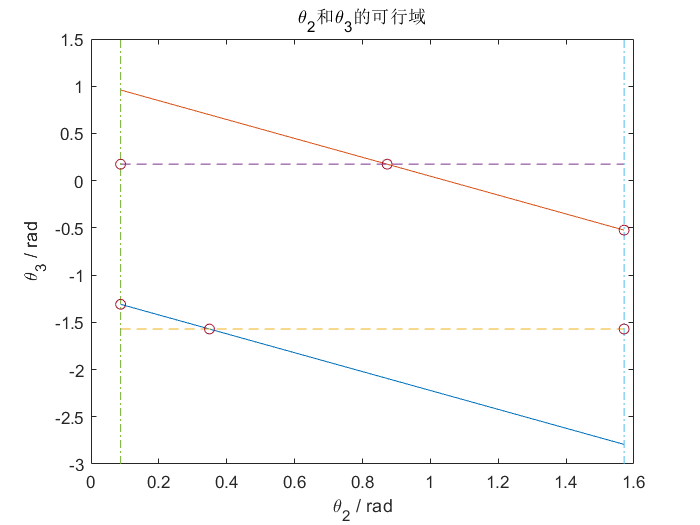

y1 = @(x) -x+limit23(1);
y2 = @(x) -x+limit23(2);
x = linspace(limit2(1), limit2(2));
figure('Name','available area')
plot(x, y1(x), x, y2(x), x, ones(size(x))*limit3(1),'--', x, ones(size(x))*limit3(2),'--')
hold on
y = linspace(-3, 1.5);
plot(ones(size(y))*limit2(1), y,'-.', ones(size(y))*limit2(2), y,'-.')
hold on
% 计算可行域的顶点
pts = zeros(6,2);
pts(1, :) = [limit2(1), limit3(2)];
pts(2, :) = [limit23(2)-limit3(2), limit3(2)];
pts(3, :) = [limit2(2), limit23(2)-limit2(2)];
pts(4, :) = [limit2(2), limit3(1)];
pts(5, :) = [limit23(1)-limit3(1), limit3(1)];
pts(6, :) = [limit2(1), limit23(1)-limit2(1)];
plot(pts(:,1), pts(:,2), 'o')
xlabel('\theta_2 / rad');
ylabel('\theta_3 / rad');
title("\theta_2和\theta_3的可行域")

这样我们就得到了$\theta_2, \theta_3$的可行域，它是一个凸多边形。根据机械臂齐次变换的特性，关节空间中可行域的边界映射到笛卡尔空间中仍是边界，因此我们可以在关节空间的边界上取适当的点，这样就可以得到工作空间的边界

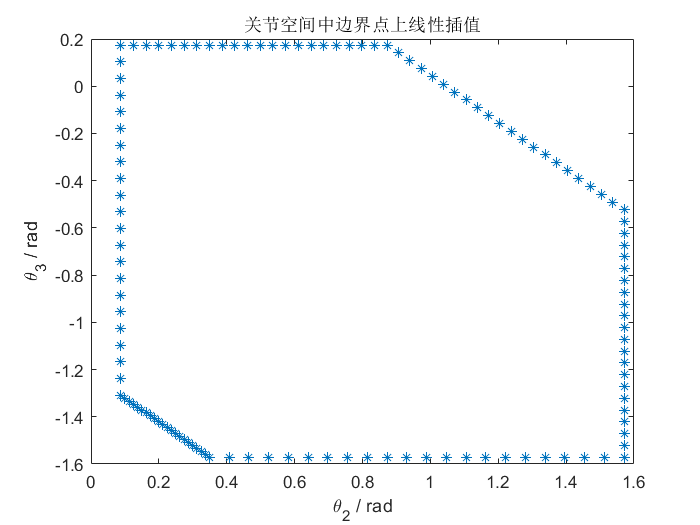

% 顺时针，线性插值，每一段取20个点
numP = 20;
points = zeros(size(pts,1)*(1+numP), size(pts,2));
for i = 1:size(pts,1)
    points((i-1)*(numP+1)+1, :) = pts(i,:);
    if i == size(pts,1)
        next = pts(1,:);
    else
        next = pts(i+1,:);
    end
    for j = 1:numP
        idx = (i-1)*(numP+1)+j+1;
        lambda = j/(numP+1);
        points(idx, :) = (1-lambda)*pts(i,:) + lambda*next;
    end
end
figure('Name','countor')
plot(points(:,1), points(:,2),'*')
title("关节空间中边界点上线性插值")
xlabel('\theta_2 / rad');
ylabel('\theta_3 / rad');

这样就得到了$\theta_2$和$\theta_3$的边界值，然后把$\theta_1$加上，再将这些值拿去遍历即可得到工作空间。

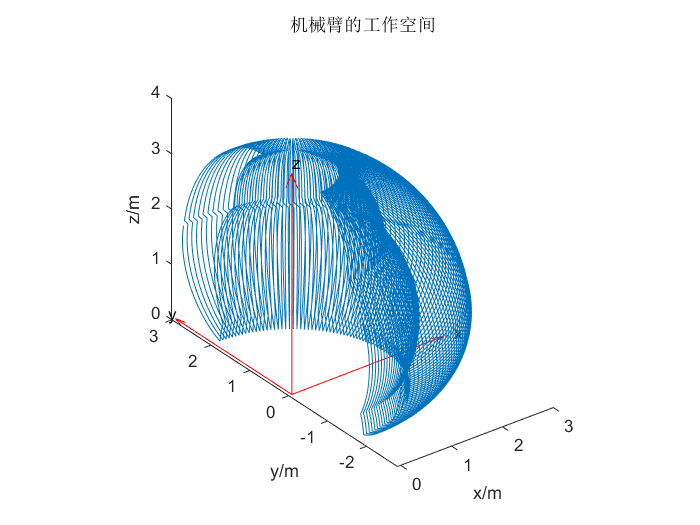

t1 = linspace(limit1(1), limit1(2));
contourPts = zeros(length(points)*length(t1), 3);
for i = 1:length(contourPts)
    j = floor((i-1)/length(points))+1;
    k = i - (j-1)*length(points);
    contourPts(i,1) = t1(j);
    contourPts(i,2:3) = points(k, :);
end
ws = zeros(size(contourPts));
for i = 1:length(ws)
    temp = robot.fkine(contourPts(i, :));
    ws(i, :) = temp(1:3, 4)';
end
figure("Name",'robot workspace')
plot3(ws(:,1), ws(:,2), ws(:,3))
hold on
quiver3(0,0,0, 1,0,0,3,"filled",'Color',[1 0 0])
text(3.2,0,0,"x");
hold on
quiver3(0,0,0, 0,1,0,3,"filled",'Color',[1 0 0])
text(0,3.2,0,"y");
hold on
quiver3(0,0,0, 0,0,1,4,"filled",'Color',[1 0 0])
text(0,0,4.2,"z");
axis equal;
title("机械臂的工作空间")
xlabel("x/m"); ylabel("y/m"); zlabel("z/m")

## 根据电机参数，仿真分析机械臂运动的参数

当各个电机都以额定转速运行时，可以根据雅可比矩阵计算出末端的速度

% 当各个电机都以额定转速运行时
motor = [500 500 500];
ratio = 10; % 减速比
dq = motor/60*2*pi/ratio;

**case 1 正常的位置**

当机械臂此时处于非奇异的位置时，可以计算末端的速度和角速度如下。

q = [pi/4, pi/6, -pi/6];
J = robot.jacobi(q);
vw = J*dq'   % 末端速度与角速度

vw =   -12.2703
    7.2720
   21.5154
    7.4048
   -7.4048
    5.2360


**case2 奇异位形**

当机械臂此时处于奇异的位置时，可以计算末端的速度和角速度如下。此时机械臂位于奇异位形，无论关节速度多大，x方向速度都为0

q = [0 0 0];
J = robot.jacobi(q);
vw = J*dq'

vw =          0
   14.7655
   22.4624
         0
  -10.4720
    5.2360


当各个电机都以一定的加速度运行时，可以根据海森矩阵计算出末端的加速度。


$$a = \dot{X}^T \frac{\partial J(x)}{\partial X} \dot{X} + J(X) \ddot{X}$$


dq = [500 500 500]'; % 角速度
ddq = [50 50 50]';   % 角加速度
ratio = 10; % 减速比
dq = dq/60*2*pi/ratio;
ddq = ddq/60*2*pi/ratio;
J = robot.jacobi([pi/6, pi/4, -pi/6]);
[H1, H2, H3] = robot.Hessian([pi/6, pi/4, -pi/6]);

a = [ dq'*H1*dq; dq'*H2*dq; dq'*H3*dq] + J(1:3,:)*ddq

a =  -168.2583
 -204.3241
  -65.9065


## 设计PD控制器

使用matlab的符号推导功能，利用牛顿欧拉法，推导出动力学方程，并将其分解成如下形式：


$$\tau  = M(\Theta)\ddot{\Theta} + V(\Theta, \dot{\Theta}) + G(\Theta)$$


save("temp.mat"); % 由于接下来使用符号推导，为避免混乱，这里先将前面所有变量保存一下
clc, clear
syms th dth ddth [3 1] real
syms th1 th2 th3 real
syms dth1 dth2 dth3 real
syms ddth1 ddth2 ddth3 real
th = [th1; th2; th3];
dth = [dth1; dth2; dth3];
ddth = [ddth1; ddth2; ddth3];

syms pi
syms m1 m2 m3 real
syms l1 l2 l3 real
syms r real
% 惯性张量
syms I1 [3 3] real
syms I2 [3 3] real
syms I3 [3 3] real
I1(1:8) = 0; I2(1:8) = 0; I3(1:8) = 0;
I1(9) = m1*r*r/2;
I2(5) = m2*l2/2*l2/2;
I2(9) = m2*l2/2*l2/2;
I3(5) = m3*l3*l3;
I3(9) = m3*l3*l3;
% 质心位置（相对每个连杆）
syms c1 [3 1] real
syms c2 [3 1] real
syms c3 [3 1] real
c1(1:2)=0; c1(3)=-l1/2;
c2(1)=l2/2; c2(2:3)=0;
c3(1)=l3; c3(2:3)=0;
Pc = [c1, c2, c3];
syms g real % 重力加速度

num = 3;
m = [m1, m2, m3];
I = cat(3, I1, I2, I3);

syms omega domega v dv vc dvc F N [3 num] real
syms f n [3 num+1] real
f(:)=0; n(:)=0;

R1 = Rmat(th(1), 0);
R2 = Rmat(th(2), pi/2);
R3 = Rmat(th(3), 0);
RH = Rmat(0, 0);
R(:,:,1) = R1;
R(:,:,2) = R2;
R(:,:,3) = R3;
R(:,:,4) = RH;
Rinv(:,:,1) = transpose(R1);
Rinv(:,:,2) = transpose(R2);
Rinv(:,:,3) = transpose(R3);
Rinv(:,:,4) = transpose(RH);

T1 = Tmat(0, 0, l1, th(1));
T2 = Tmat(pi/2, 0, 0, th(2));
T3 = Tmat(0, l2, 0, th(3));
TH = Tmat(0, l3, 0, 0);
P = [T2(1:3,4), T3(1:3,4), TH(1:3,4)];


% 外推
for i = 0:num-1
    if(i == 0)
        omega(:, i+1) = dth(i+1)*[0;0;1];
        domega(:,i+1) = ddth(i+1)*[0;0;1];
        dv(:, i+1) = Rinv(:,:,i+1) * [0;0;-g];
    else
        omega(:, i+1) = Rinv(:,:,i+1)*omega(:,i) + dth(i+1)*[0;0;1];
        domega(:,i+1) = Rinv(:,:,i+1)*domega(:,i) + cross(Rinv(:,:,i+1)*omega(:,i), dth(i+1)*[0;0;1]) + ddth(i+1)*[0;0;1];
        dv(:, i+1) = Rinv(:,:,i+1)*( cross(domega(:,i),P(:,i))+cross(omega(:,i),cross(omega(:,i),P(:,i))) + dv(:,i) );
    end
    
    dvc(:, i+1) = cross(domega(:,i+1), Pc(:,i+1)) + cross(omega(:,i+1), cross(omega(:,i+1),Pc(:,i+1))) + dv(:,i+1);
    F(:, i+1) = m(i+1)*dvc(:, i+1);
    N(:, i+1) = I(:,:,i+1)*domega(:,i+1) + cross(omega(:,i+1), I(:,:,i+1)*omega(:,i+1));
end

% 内推
for i = num:-1:1
    f(:,i) = R(:,:,i+1)*f(:,i+1) + F(:,i);
    n(:,i) = N(:,i) + R(:,:,i+1)*n(:,i+1) + cross(Pc(:,i), F(:,i))+ cross(P(:,i), R(:,:,i+1)*f(:,i+1));
end


提取出$M(\Theta)$

tau = n(3, 1:3);
tau = transpose(tau);
syms M [length(tau) num]
for i = 1:length(tau) % i: 第i个关节扭矩
    t = tau(i);
    for j = 1:num % j: 第j个关节变量
        [cx, tx] = coeffs(t, ddth(j));
        if ismember(ddth(j), tx)
            M(i, j) = cx(1);
        else
            M(i, j) = 0;
        end
    end
end
M = simplify(M)

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{{l_{2}}^{2}\,m_{2}}{4}+\frac{{l_{2}}^{2}\,m_{3}}{2}+{l_{3}}^{2}\,m_{3}+\frac{m_{1}\,r^{2}}{2}+{l_{3}}^{2}\,m_{3}\,\cos\left(2\,{\mathrm{th}}_{2}+2\,{\mathrm{th}}_{3}\right)+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,{\mathrm{th}}_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{3}\,\cos\left(2\,{\mathrm{th}}_{2}\right)}{2}+l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\right)+l_{2}\,l_{3}\,m_{3}\,\cos\left(2\,{\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right) & 0 & 0\\ 0 & \frac{{l_{2}}^{2}\,m_{2}}{2}+{l_{2}}^{2}\,m_{3}+\sigma_{2}+2\,l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\right) & \sigma_{1}\\ 0 & \sigma_{1} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,m_{3}\,\left(2\,l_{3}+l_{2}\,\cos\left({\mathrm{th}}_{3}\right)\right)\\ \sigma_{2}=2\,{l_{3}}^{2}\,m_{3} \end{array}$$

提取出$V(\Theta, \dot{\Theta}) $

syms G [length(tau) 1]
for i = 1:length(tau)
    t = tau(i);
    [cx, tx] = coeffs(t, g);
    if ismember(g, tx)
        G(i) = cx(1);
    else
        G(i) = 0;
    end
end
G = simplify(G)

$$G = \left(\begin{array}{c} 0\\ -\frac{l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}-l_{2}\,m_{3}\,\cos\left({\mathrm{th}}_{2}\right)-l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)\\ -l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right) \end{array}\right)$$

提取出$G(\Theta)$

syms V [length(tau) 1]
V = tau - M*ddth - G;
V = simplify(V)

$$V = \begin{array}{l} \left(\begin{array}{c} -\frac{{\mathrm{dth}}_{1}\,\left({\mathrm{dth}}_{2}\,{l_{2}}^{2}\,m_{2}\,\sin\left(2\,{\mathrm{th}}_{2}\right)+2\,{\mathrm{dth}}_{2}\,{l_{2}}^{2}\,m_{3}\,\sin\left(2\,{\mathrm{th}}_{2}\right)+4\,{\mathrm{dth}}_{2}\,{l_{3}}^{2}\,m_{3}\,\sigma_{1}+4\,{\mathrm{dth}}_{3}\,{l_{3}}^{2}\,m_{3}\,\sigma_{1}+4\,{\mathrm{dth}}_{2}\,l_{2}\,l_{3}\,m_{3}\,\sigma_{2}+2\,{\mathrm{dth}}_{3}\,l_{2}\,l_{3}\,m_{3}\,\sigma_{2}+2\,{\mathrm{dth}}_{3}\,l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\right)\right)}{2}\\ \frac{l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}+l_{2}\,m_{3}\,\cos\left({\mathrm{th}}_{2}\right)+l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)-g\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)-\frac{g\,l_{2}\,m_{2}\,\cos\left({\mathrm{th}}_{2}\right)}{2}-g\,l_{2}\,m_{3}\,\cos\left({\mathrm{th}}_{2}\right)+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}\,\sin\left(2\,{\mathrm{th}}_{2}\right)}{4}+\frac{{{\mathrm{dth}}_{1}}^{2}\,{l_{2}}^{2}\,m_{3}\,\sin\left(2\,{\mathrm{th}}_{2}\right)}{2}+{{\mathrm{dth}}_{1}}^{2}\,{l_{3}}^{2}\,m_{3}\,\sigma_{1}-{{\mathrm{dth}}_{3}}^{2}\,l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\right)+{{\mathrm{dth}}_{1}}^{2}\,l_{2}\,l_{3}\,m_{3}\,\sigma_{2}-2\,{\mathrm{dth}}_{2}\,{\mathrm{dth}}_{3}\,l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\right)\\ \frac{l_{3}\,m_{3}\,\left(2\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)-2\,g\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)+2\,{{\mathrm{dth}}_{1}}^{2}\,l_{3}\,\sigma_{1}+{{\mathrm{dth}}_{1}}^{2}\,l_{2}\,\sin\left({\mathrm{th}}_{3}\right)+2\,{{\mathrm{dth}}_{2}}^{2}\,l_{2}\,\sin\left({\mathrm{th}}_{3}\right)+{{\mathrm{dth}}_{1}}^{2}\,l_{2}\,\sigma_{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,{\mathrm{th}}_{2}+2\,{\mathrm{th}}_{3}\right)\\ \sigma_{2}=\sin\left(2\,{\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right) \end{array}$$

根据上面符号推到的结果，就可以设计PD控制器。具体的设计通过simulink实现，详情见下一节。

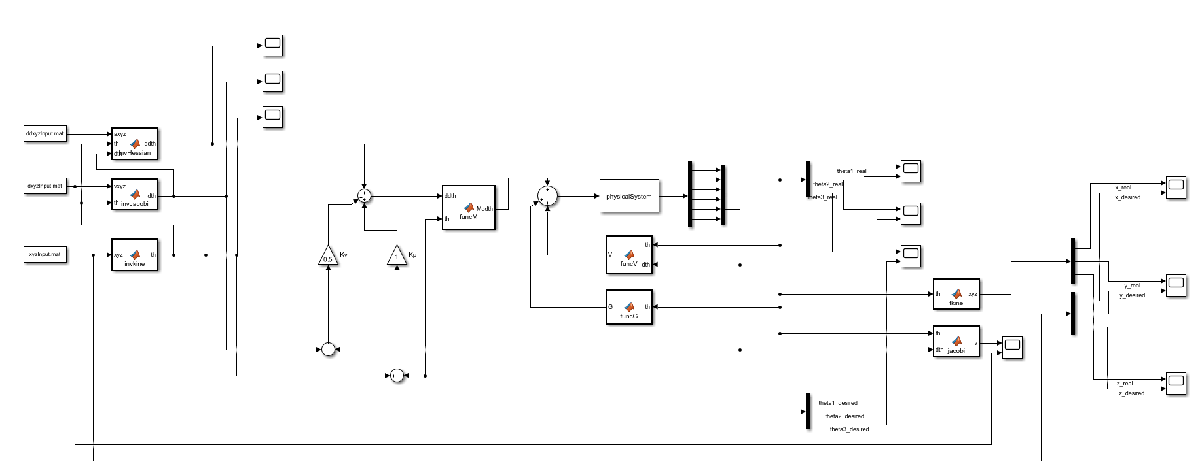

## 轨迹规划与控制仿真

将轨迹规划封装到trajectory.m文件中，调用此函数，可以直接生成直线-抛物线轨迹。例如

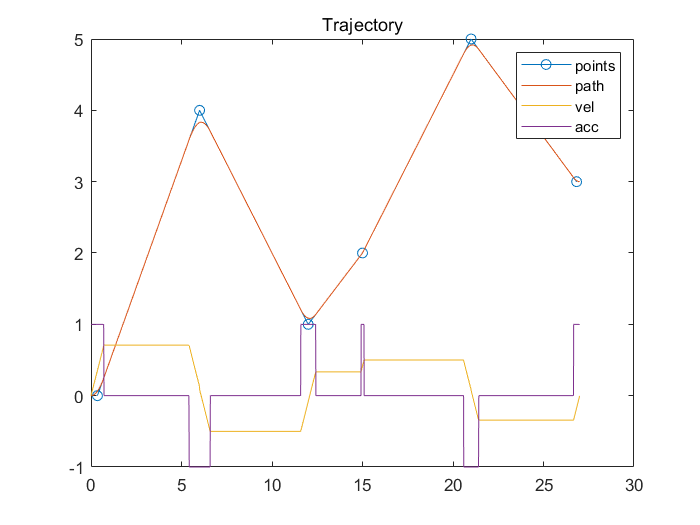

clc, clear
load temp.mat % 重新加载之前保存的变量
theta = [0, 4, 1, 2, 5, 3]; % 各个中间点的位置
td = [6, 6, 3, 6, 6];       % 每个中间点之间的时间间隔
alpha = [1, 1, 1, 1, 1, 1]; % 过渡阶段的加速度
[t_all, y_all, dy_all, ddy_all] = trajectory(theta, td, alpha);

因此，我们可以生成关节末端执行器在x、y、z三个方向上的轨迹

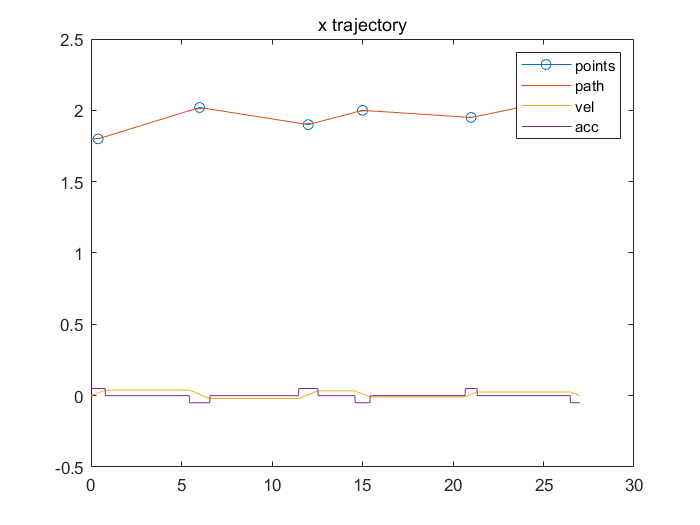

x = [2.1, 2.32, 2.2, 2.3, 2.25, 2.4]-0.3; % 各个中间点的位置
td = [6, 6, 3, 6, 6];       % 每个中间点之间的时间间隔
alpha = [0.05, 0.05, 0.05, 0.05, 0.05, 0.05]; % 过渡阶段的加速度
[t_all, x_all, dx_all, ddx_all] = trajectory(x, td, alpha, "x trajectory");

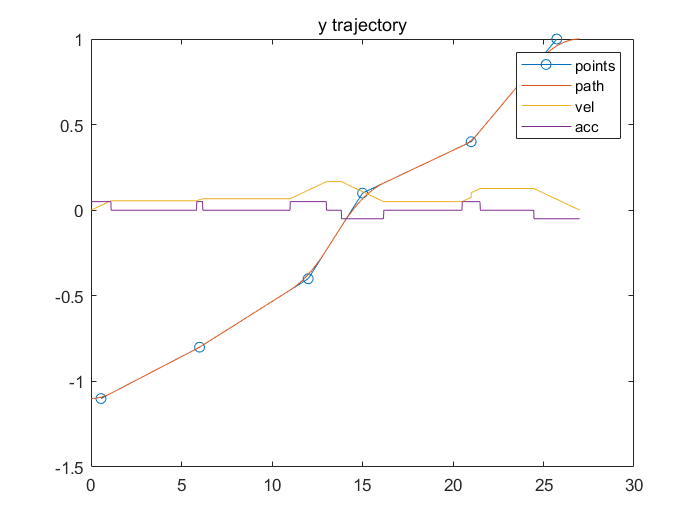

y = [-1.1, -0.8, -0.4, 0.1, 0.4, 1]; % 各个中间点的位置
td = [6, 6, 3, 6, 6];       % 每个中间点之间的时间间隔
alpha = [0.05, 0.05, 0.05, 0.05, 0.05, 0.05]; % 过渡阶段的加速度
[t_all, y_all, dy_all, ddy_all] = trajectory(y, td, alpha, "y trajectory");

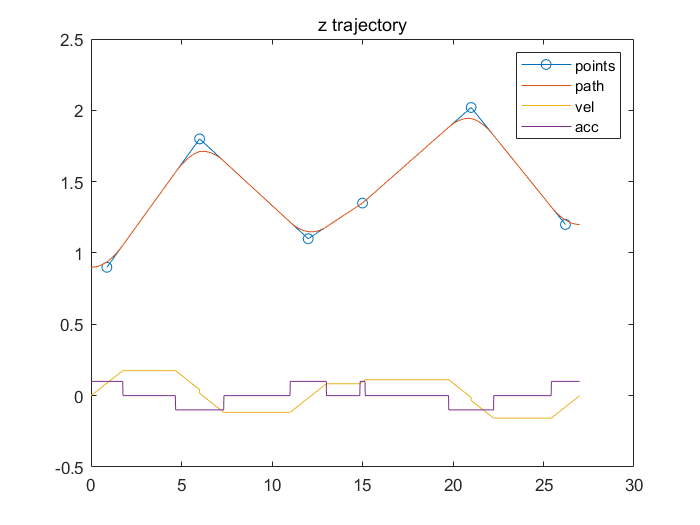

z = [1, 1.9, 1.2, 1.45, 2.12 1.3]-0.1; % 各个中间点的位置
td = [6, 6, 3, 6, 6];       % 每个中间点之间的时间间隔
alpha = [0.1, 0.1, 0.1, 0.1, 0.1, 0.1]; % 过渡阶段的加速度
[t_all, z_all, dz_all, ddz_all] = trajectory(z, td, alpha, "z trajectory");

xyzInput = [t_all; x_all; y_all; z_all];
dxyzInput = [t_all; dx_all; dy_all; dz_all];
ddxyzInput = [t_all; ddx_all; ddy_all; ddz_all];

可以将运动轨迹画在工作空间中，如下所示。

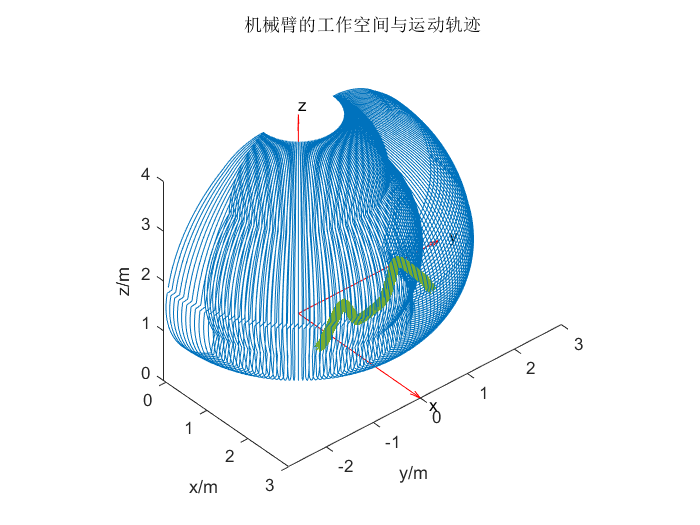

figure("Name",'robot workspace and trajectory')
plot3(ws(:,1), ws(:,2), ws(:,3))
hold on
quiver3(0,0,0, 1,0,0,3,"filled",'Color',[1 0 0])
text(3.2,0,0,"x");
hold on
quiver3(0,0,0, 0,1,0,3,"filled",'Color',[1 0 0])
text(0,3.2,0,"y");
hold on
quiver3(0,0,0, 0,0,1,4,"filled",'Color',[1 0 0])
text(0,0,4.2,"z");
plot3(xyzInput(2,:)',xyzInput(3,:)',xyzInput(4,:)', '*')
axis equal;
title("机械臂的工作空间与运动轨迹")
xlabel("x/m"); ylabel("y/m"); zlabel("z/m")
view([49.11 36.90])

将轨迹规划的结果保存到文件中，用于接下来的仿真。

save('xyzInput.mat', "xyzInput");
save('dxyzInput.mat', "dxyzInput");
save('ddxyzInput.mat', "ddxyzInput");

仿真程序在simulink中，打开simulation.slx，运行即可。

## simulink仿真

仿真思路如下。

系统的输入是机械臂在笛卡尔空间中的目标位置、速度、加速度，通过逆运动学解、逆雅可比矩阵、海森矩阵即可计算出机械臂关节的目标角度、角速度、角加速度。

然后，通过PD控制对机械臂进行线性控制，控制方法参考课本图10-5

值得一提的是，物理模型部分使用simulink中的s-function来实现，具体代码写在了physicalSystem.m文件中，在simulink中它对应的模块是physicalSystem。

仿真效果如下：